images\seashell_five.jpg


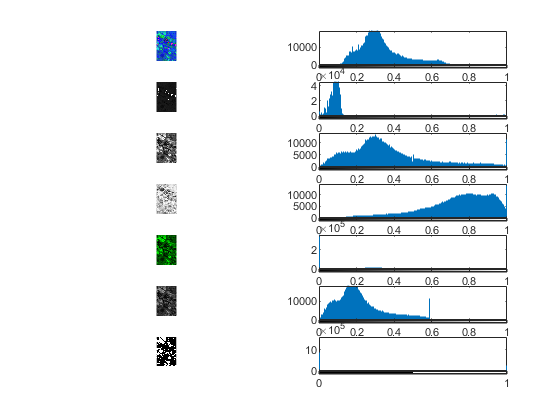

images\shellfish_four.jpg


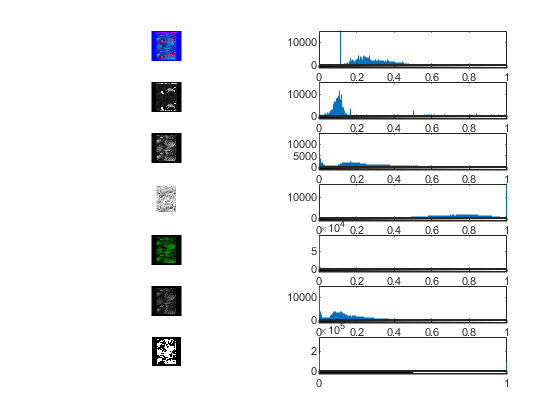

images\starfish.jpg


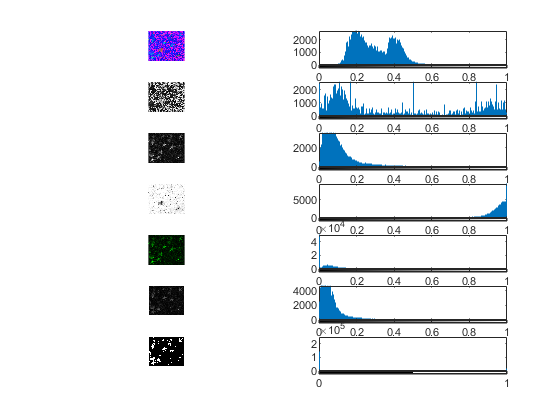

images\starfish_17.jpg


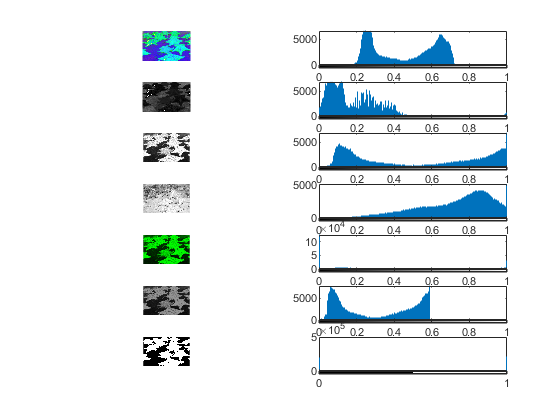

images\starfish_5.jpg


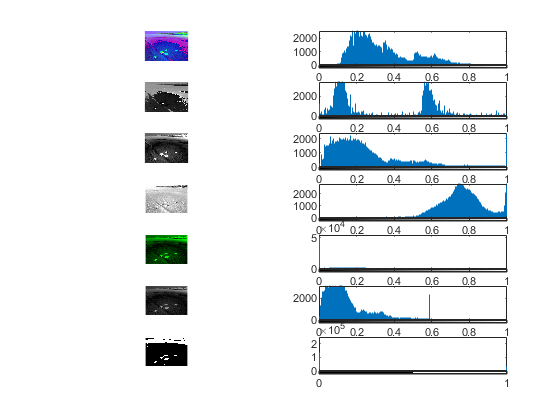

images\starfish_map0.jpg


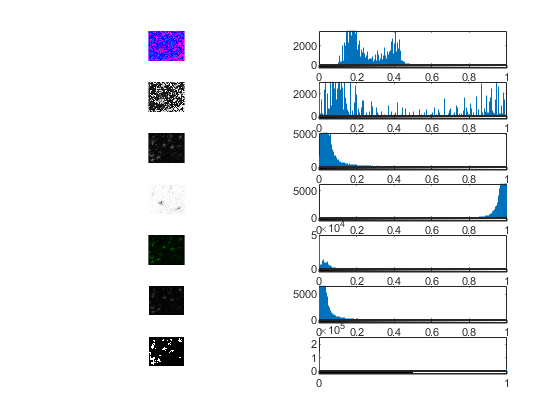

images\starfish_map1.jpg


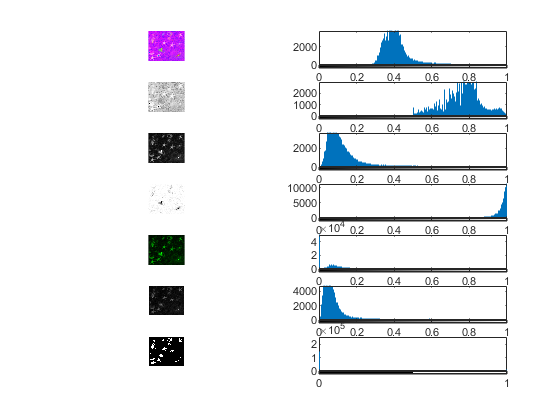

images\starfish_map2.jpg


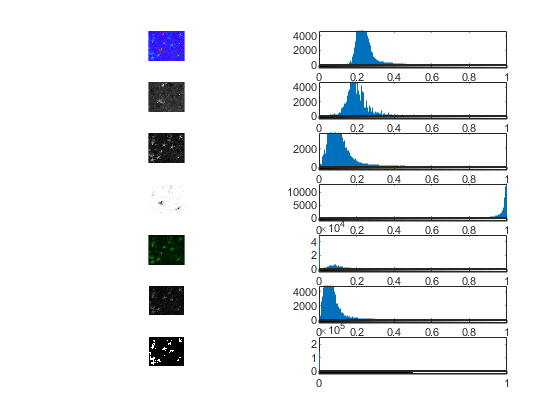

images\starfish_map3.jpg


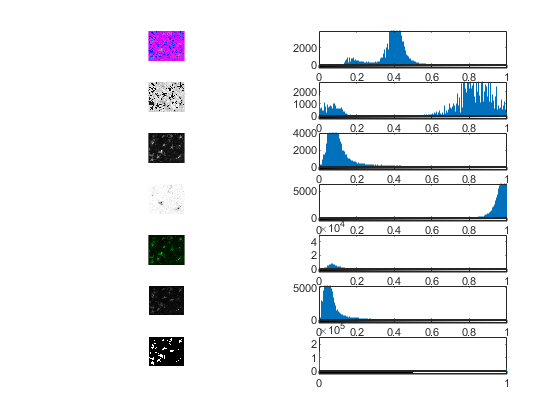

images\starfish_noise1.jpg


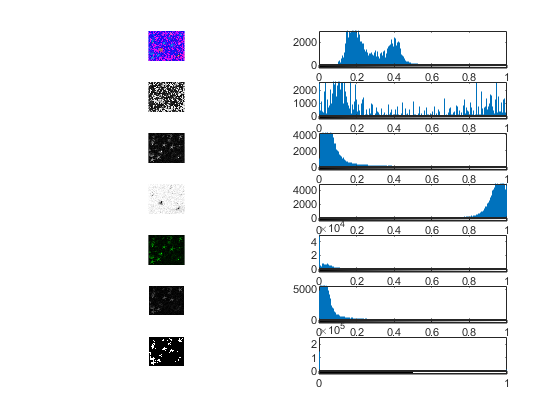

images\starfish_noise10.jpg


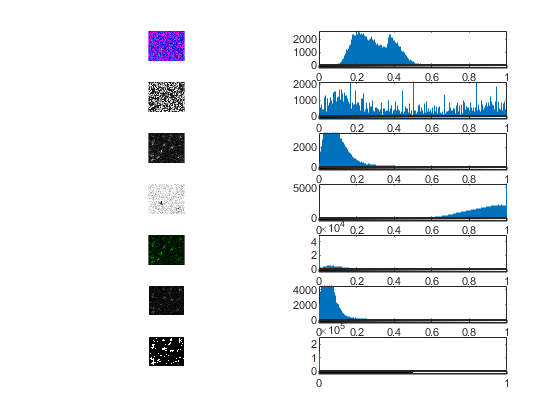

images\starfish_noise2.jpg


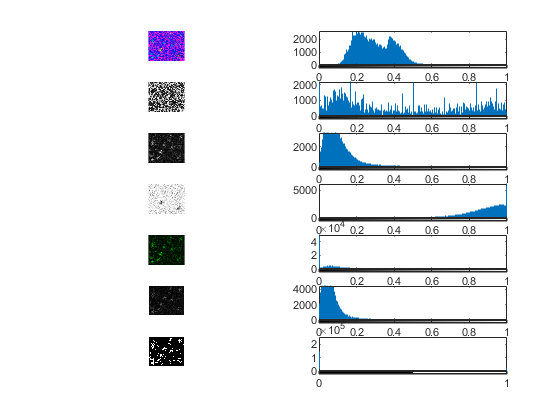

images\starfish_noise3.jpg


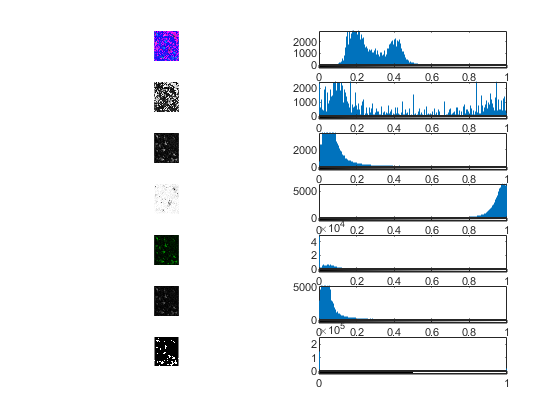

images\starfish_noise4.jpg


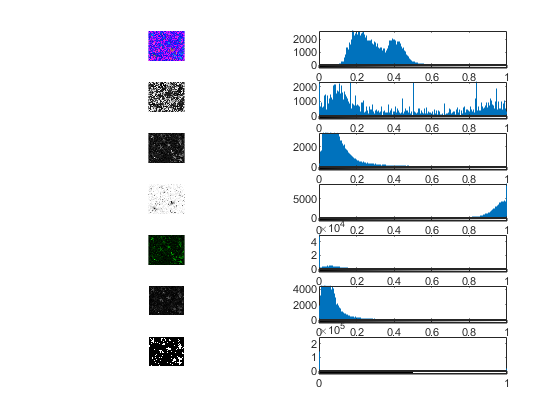

images\starfish_noise5.jpg


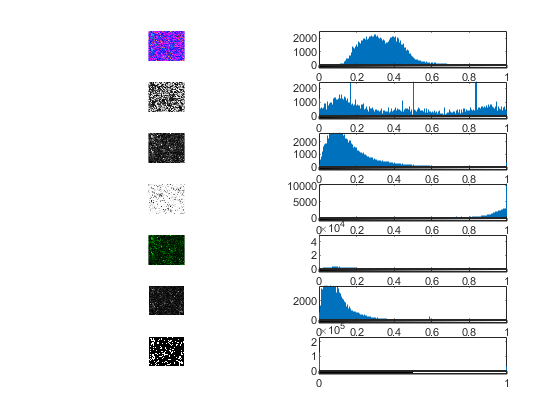

images\starfish_noise6.jpg


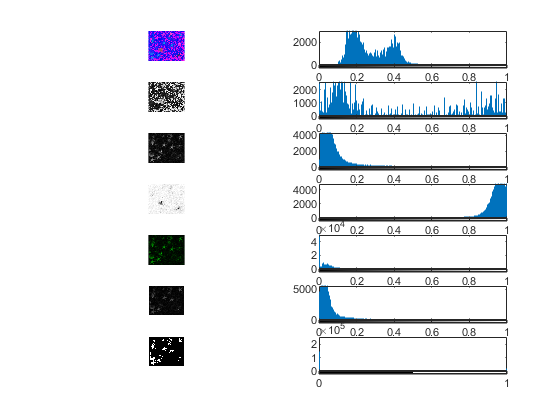

images\starfish_noise7.jpg


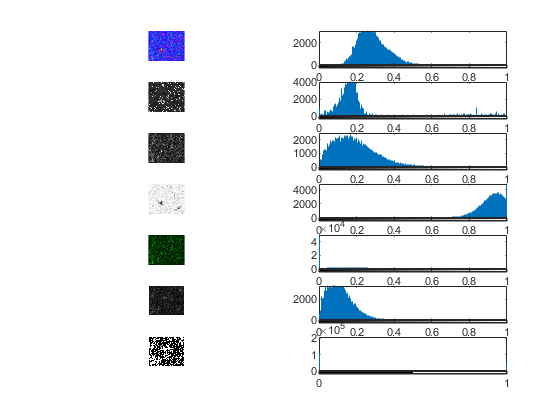

images\starfish_noise8.jpg


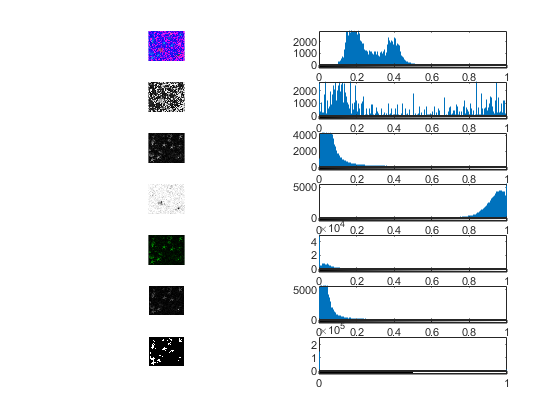

images\starfish_noise9.jpg


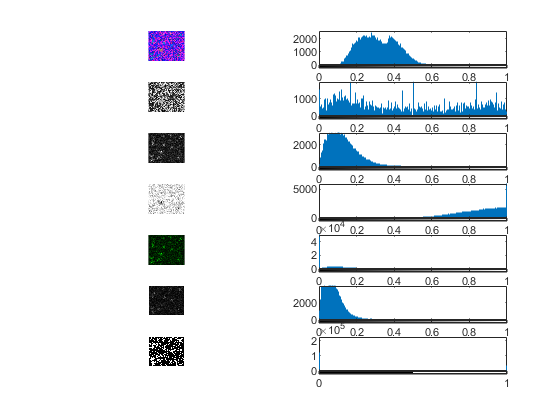

images\starfish_overlaid.jpg


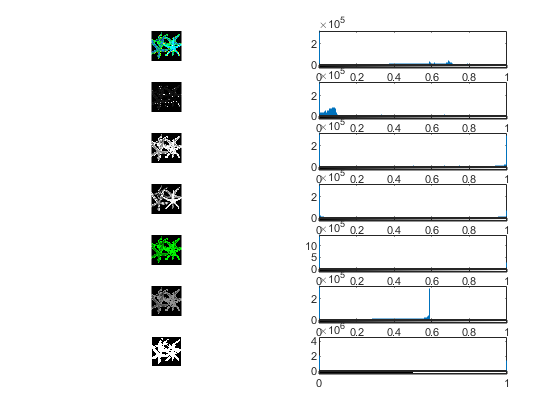

files = GetFilesInSubDir("images");

r = 7;
c = 2;
for i = 1:numel(files)
    filepath = files(i);
    
    disp(filepath)
    
    im = imread(filepath);
%     im = imgaussfilt3(im, 1); 
    
    im = rgb2hsv(im);
    [ch1, ch2, ch3] = imsplit(im);
    
    figure
    subplot(r,c,1);
    imshow(im)
    subplot(r,c,2);
    allChHist = imhist(rgb2gray(im));
    imhist(rgb2gray(im))
    
    subplot(r,c,3);
    imshow(ch1)
    subplot(r,c,4);
    ch1Hist = imhist(ch1);
    imhist(ch1)
    
    subplot(r,c,5);
    imshow(ch2)
    subplot(r,c,6);
    ch2Hist = imhist(ch2);
    imhist(ch2)
    
    subplot(r,c,7);
    imshow(ch3)
    subplot(r,c,8);
    ch3Hist = imhist(ch3);
    imhist(ch3)
    
%     Get rid of hue channel which generally contains most of noise
    svIm = im;
    svIm(:,:,1) = 0;
    svIm(:,:,3) = 0;
    subplot(r,c,9);
    imshow(svIm)
    subplot(r,c,10);
%     svImHist = imhist(svIm);
    imhist(svIm)
    
%     Binarise
% %     Inspect in rgb
%     rgbIm = hsv2rgb(svIm);
    svIm(:,:,1) = 0;
%     svIm(:,:,2) = svIm(:,:,2) > 0.4;%0.6; 
%     svIm(:,:,3) = svIm(:,:,3) > 0.4;%0.6; 
    grayIm = rgb2gray(svIm);
    subplot(r,c,11);
    imshow(grayIm)
    subplot(r,c,12);
%     rgbImHist = imhist(svIm);
    imhist(grayIm)
    
    level = graythresh(grayIm);
    imT = imbinarize(grayIm,level);
    subplot(r,c,13);
    imshow(imT)
    subplot(r,c,14);
%     rgbImHist = imhist(svIm);
    imhist(imT)
    
% %     Threshold out dark colours
%     im = svIm;
%     im(:,:,2) = im(:,:,2) > 0.6; 
%     im(:,:,3) = im(:,:,3) > 0.6; 
%     subplot(r,c,11);
%     imshow(im)
%     subplot(r,c,12);
% %     rgbImHist = imhist(svIm);
%     imhist(im)
    
% %     Inspect in rgb
%     rgbIm = hsv2rgb(svIm);
%     subplot(r,c,11);
%     imshow(rgbIm)
%     subplot(r,c,12);
% %     rgbImHist = imhist(svIm);
%     imhist(rgbIm)
end

function filepaths = GetFilesInSubDir(subDir)
    files = dir(subDir);
    files = files(~ismember({files.name}, {'.', '..'})); % Remove navigation elements from struct.
    filepaths = subDir + "\" + {files.name};
end
